%  #############################################  %
%       Code created by the Panettone team        %
%  #############################################  %

# **Plate recognition system**

## **Read image from datastore**

% Clear the workspace to avoid interferences when calling different
% pictures from ds.Files
clear all, close all 

% Creating a dataset with the gathered pictures
ds = imageDatastore("Pictures/","IncludeSubfolders",true);

a = ds.Files(21);  % Opening the selected image

When picking up the pictures from the datastore, the function writes the direction from the picture in a variable Cell. To be able to read it as a picture, the cell content (Picture directory) needs to be turned into a string variable.

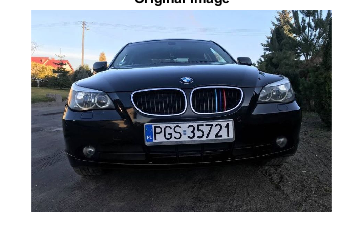

ab = sprintf('%s', a{:});  % Turning the directory inside the cell into a string

abc = imread(ab);  % Reading and visualizing the image
figure(1);
imshow(abc)
title('Original image')

## **Crop original image**

To reduce the number of elements which can cause interferences with the code, the idea is to remove from the picture the biggest amount of unnecessary surface possible. It is assumable that in all pictures the plate is going to be at the bottom half of the image, centered at the middle. The first part of the assumption is easily filled in all pictures, for all plates being at the botom part of the cars. The second part of the assumption can be false, as if the camera caught the picture while the car was making a turn to get inside the parking, there is a chance the plate is displaced to one side and therefore croped out. 

Taking into account this two considerations, and to make things easier it has been decided to work with the bottom half of the picture removing only the top part and no areas at the sides.

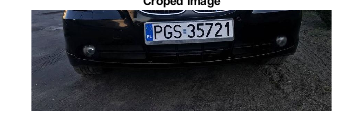

[heigth, width, chan] = size(abc);  % Finding the pictures dimensions to crop out the top half.

%   @heigth --> picture number of rows each one pixel thick
%   @width --> picture number of coumns each one pixel thick
%   @chan --> number of channels, as it is an RGB picture it has 3. Not used
%             but necessary for the function syntax.


d_heigth = round(heigth/2);  % Dividing heigth in two: upper and lower sections


figure(2);
rect = [0 d_heigth width heigth];  % Croping the image by the lower section to get rid of the upper one.
croped = imcrop(abc, rect);
imshow(croped)
title('Croped image')

## **Create mask of the image to separate car from plate**

After trying a lot of ideas and ways to maske the image, the final approach is to work with the RGB values of the image. The goal of this mask is to turn dark grays and blacks into 0 and all other values to 1. The reason for this mask is most plates have a dark contourn (mostly black, sometimes dark gray), which we can take advantage of to isolate the plate as a connected component (CC) to work with later. If this contourn is neither dark nor well defined the plate will not be well isolated and no Finalcandidate found. (Later explained).

There is another masks later in the code if this one doesn't work to check for lighrter plate contourns. 

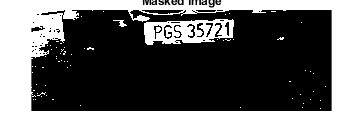

mask = ones(d_heigth, width);  % Ones matrix with the croped image sizes

for i = 1:d_heigth  % Loop through all image pixels to apply the mask
    for j = 1:width

        % Turn pixels darker than 90 (threshold) to 0
        if croped(i, j, 1) < 90 && croped(i, j, 2) < 90 && croped(i, j, 3) < 90  
            mask(i, j) = 0;  
        end
    end
end

figure(3);
imshow(mask)
title('Masked image')

## **Binarization of the mask to create components**

Even though the masked image should already be a binary image for all values are either one or zero, when working with the CCs by using the function regionprops, there would be some errors not finding all the components correctly. Using imbinarize over the masked image helps fixing this issue.

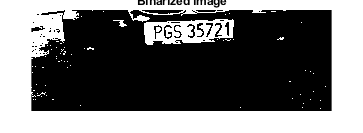

% Binarizing the image
figure(4);
imBin = imbinarize(mask);
imshow(imBin)
title('Binarized image')


disp('Connected components properties')

Connected components properties


canAreas = regionprops(imBin)  % Getting the desired connected components properties. Only area and

canAreas = 278×1 struct array with fields:
    Area
    Centroid
    BoundingBox


                               % boundingbox are necessary so the default parameters work well.
                     
bBoxes = vertcat(canAreas.BoundingBox);  % Concatening vertically the bounding boxes in four column 
                                         % table for easier manipulation  


## Find plate candidates from the components

For any of this CCs to be considered  a candidate to be the car plate, they have to pass a two parameter filter.

    The first parameter is shape. Assuming a plate has a rectangular shape with a bigger width than height, all CCs which have bigger height than width are eliminated from     the candidates list.

    The second parameter is height-width ratio. Modern car plates are standarized to be 52 cm wide and 11 cm high which makes a ratio of 52/11 = 4.7 roughly 5. Taking into account the tilted plates which have a lower ratio, for they have bigger height, we can consider 4 as the ratio value as a result of some trials. Using some tolerances as to ensure the fitting of all plates (with and without blue part, tilted or not tilted, etc.) the final ratio numbers are between:  

   Lower limit --> 3 times height = width

   Upper limit --> 6 times height = width     

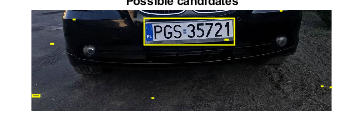

% Finding candidates accorgind to the two parameter filter
Candidates = find([bBoxes(:,3)] > bBoxes(:,4)*3 & [bBoxes(:,3)] < bBoxes(:,4)*6 );

figure(5);
imshow(croped)
title('Possible candidates')

% Drawing a rectangle over each Candidate for easily visual recognition
for n=1:length(Candidates)
    rectangle("Position", canAreas(Candidates(n)).BoundingBox, "EdgeColor", "y", "LineWidth", 1)
end

## Indentify plate from candidates

The approach used to identify the plate over all the final candidates has been to find blue pixels either inside the candidates or at their left. The reason for this being, this algorithm sometimes finds the plate without the blue country box, and other times with it. If the plate includes the blue box, the blue pixels are going to be inside the component and, if the plate does not include the blue box, the blue pixels are outside it.

As the blue box has the stars at the upper part, and the country letters at the bottotm, it has been decided to chech one pixel at the middle therefore the height value of this pixel is going to be the Bounding Box height's middle value: @bboxes/2.

As for the distance from the bBox border it has been arbitrarily decided the value would be +-10 pixels. 

    @bBoxes(Candidates, 1) - 10 or bBoxes(Candidates, 1) + 10.

   @bBoxes(Candidates, 1) --> x bounging box starting value.

The chosen pixel will be found by combining adding or substracting 10 pixels to bBoxes(Candidates, 1) and using bBoxes(Candidates, 4) /2.

#### Blue identification:

After checking on what defines blue color it has been stated 3 parameters:

- Red channel value is the smallest and way smaller than blue.

- Green channel value is bigger than red and also smaller than blue.

- Blue channel value is the biggest by far.

This three aspects are always true, but not always with the same ratios nor intensities due to the influence of shades and the type of blue. Therefore this three parameters are going to be the method to define whether exists a blue pixel near the candidate. The values defined below at the for loop to find the blue pixel have been defined acording to the darkest blue found at the plates of the database.

Candidates_HEIGHT = bBoxes(Candidates, 4) /2;
Candidates_yPOS_left = bBoxes(Candidates, 1) - 10;
Candidates_yPOS_right = bBoxes(Candidates, 1) + 10;

Origin_yPOS = bBoxes(Candidates, 2);

FinalCandidate = []; % Creating an empty variable to store the final candidate index

for n=1:length(Candidates) % Loop through all candidates
    
    % Check that no candidates are to close to the border so when adding or
    % substracting 10 pixels the pixel value will be out of the image and
    % rise an error.
    if (round(Candidates_yPOS_left(n)) > 0 && round(Candidates_yPOS_left(n)) < width) && (round(Candidates_yPOS_right(n)) > 0 && round(Candidates_yPOS_right(n)) < width)
        
        % Check if the candidate has the blue pixel either at the right
        % (inside) or at the left of the bBox border.
        if ((croped(round(Origin_yPOS(n)) + round(Candidates_HEIGHT(n)), round(Candidates_yPOS_left(n)), 1) + 38) < croped(round(Candidates_HEIGHT(n)) + round(Origin_yPOS(n)), round(Candidates_yPOS_left(n)), 3) && (croped(round(Candidates_HEIGHT(n)) + round(Origin_yPOS(n)), round(Candidates_yPOS_left(n)), 2) + 30) < croped(round(Candidates_HEIGHT(n)) + round(Origin_yPOS(n)), round(Candidates_yPOS_left(n)), 3) && croped(round(Candidates_HEIGHT(n)) + round(Origin_yPOS(n)), round(Candidates_yPOS_left(n)), 3)> 50)...
            || ((croped(round(Origin_yPOS(n)) + round(Candidates_HEIGHT(n)), round(Candidates_yPOS_right(n)), 1) + 38) < croped(round(Origin_yPOS(n)) + round(Candidates_HEIGHT(n)), round(Candidates_yPOS_right(n)), 3) && (croped(round(Origin_yPOS(n)) + round(Candidates_HEIGHT(n)), round(Candidates_yPOS_right(n)), 2) + 30) < croped(round(Origin_yPOS(n)) + round(Candidates_HEIGHT(n)), round(Candidates_yPOS_right(n)), 3) && croped(round(Origin_yPOS(n)) + round(Candidates_HEIGHT(n)), round(Candidates_yPOS_right(n)), 3)> 50) 
            
            % Delete any Candidate which meet all previous requisits but
            % doesn't have the correct dimensions. The plate dimensions are
            % estimated acording to all iamges having similar shapes
            % (knowing the dimensions of the pictures taken by the system)
            % an giving some range, considering the car position must not
            % always be the same and therefore niether the plate which
            % might change in size due to distance.
            if canAreas(Candidates(n)).Area > 4000 && canAreas(Candidates(n)).Area < 15000
                FinalCandidate = Candidates(n);
            end
        end
    end
end

## Second threshold if there are zero final candidate

If there is no final candidate it can be asumed that the plate analysed doesn't have a dark contourn and therefore it was not well isolated from the rest of the car. For this reason it has been decided to repeat the detection process applying another mask with a different treshold and also cheking for intensity values with the aim of turn silver and gray colors into 0 and isolate the plate.

The threshold has been stablished by trial and error.

As the code is pretty much the same as before, this time won't be comented.

### Create new mask

if isempty(FinalCandidate)
    disp("Final candidate empty")
    %create new threshold
    mask = zeros(d_heigth, width);  % Ones matrix with the croped image sizes
    
    for i = 1:d_heigth  % Loop through all image pixels to apply the mask
        for j = 1:width
    
            % Turn pixels higher than 
            if croped(i, j, 1) > 125 && croped(i, j, 2) > 125 && croped(i, j, 3) > 125 && abs(croped(i, j, 1) - croped(i, j, 2)) < 20 && abs(croped(i, j, 1) - croped(i, j, 3)) < 20 && abs(croped(i, j, 2) - croped(i, j, 3)) < 20
                mask(i, j) = 1;  
            end
        end
    end
    
    figure(3);
    imshow(mask)
    title('Masked image')

    % Binarizing the image
    figure(4);
    imBin = imbinarize(mask);
    imshow(imBin)
    title('Binarized image')

    %Find new candidates 

    disp('Connected components properties')
    canAreas = regionprops(imBin)  % Getting the desired connected components properties. Only area and
                                   % boundingbox are necessary so the default parameters work well.
                         
    bBoxes = vertcat(canAreas.BoundingBox);  % Concatening vertically the bounding boxes in four column 
                                             % table for easier manipulation  
    % Finding candidates accorgind to the two parameter filter
    Candidates = find([bBoxes(:,3)] > bBoxes(:,4)*3 & [bBoxes(:,3)] < bBoxes(:,4)*6 );
    
    figure(5);
    imshow(croped)
    title('Possible candidates')
    
    % Drawing a rectangle over each Candidate for easily visual recognition
    for n=1:length(Candidates)
        rectangle("Position", canAreas(Candidates(n)).BoundingBox, "EdgeColor", "y", "LineWidth", 1)
    end

    %calculate new final candidate

    Candidates_HEIGHT = bBoxes(Candidates, 4) /2;
    Candidates_yPOS_left = bBoxes(Candidates, 1) - 10;
    Candidates_yPOS_right = bBoxes(Candidates, 1) + 10;
    
    Origin_yPOS = bBoxes(Candidates, 2);
    
    FinalCandidate = [];
    
    for n=1:length(Candidates)
    
        if (round(Candidates_yPOS_left(n)) > 0 && round(Candidates_yPOS_left(n)) < width) && (round(Candidates_yPOS_right(n)) > 0 && round(Candidates_yPOS_right(n)) < width)
    
            if ((croped(round(Origin_yPOS(n)) + round(Candidates_HEIGHT(n)), round(Candidates_yPOS_left(n)), 1) + 38) < croped(round(Candidates_HEIGHT(n)) + round(Origin_yPOS(n)), round(Candidates_yPOS_left(n)), 3) && (croped(round(Candidates_HEIGHT(n)) + round(Origin_yPOS(n)), round(Candidates_yPOS_left(n)), 2) + 30) < croped(round(Candidates_HEIGHT(n)) + round(Origin_yPOS(n)), round(Candidates_yPOS_left(n)), 3) && croped(round(Candidates_HEIGHT(n)) + round(Origin_yPOS(n)), round(Candidates_yPOS_left(n)), 3)> 50)...
                || ((croped(round(Origin_yPOS(n)) + round(Candidates_HEIGHT(n)), round(Candidates_yPOS_right(n)), 1) + 38) < croped(round(Origin_yPOS(n)) + round(Candidates_HEIGHT(n)), round(Candidates_yPOS_right(n)), 3) && (croped(round(Origin_yPOS(n)) + round(Candidates_HEIGHT(n)), round(Candidates_yPOS_right(n)), 2) + 30) < croped(round(Origin_yPOS(n)) + round(Candidates_HEIGHT(n)), round(Candidates_yPOS_right(n)), 3) && croped(round(Origin_yPOS(n)) + round(Candidates_HEIGHT(n)), round(Candidates_yPOS_right(n)), 3)> 50) 
                
                % When deleting the gray plate border, some plates get
                % smaller than with plates with black borders. This is the
                % reason the lower border value is also smaller.
                if canAreas(Candidates(n)).Area > 2000 && canAreas(Candidates(n)).Area < 15000
                    FinalCandidate = Candidates(n);
                end
            end
        end
    end

end

If the plate is not found, the found plate error will be risen up.

if isempty(FinalCandidate)
    display('Error finding plate. Plate not found.')
end

## Find final plate

When there is a Final candidate the next step is to crop the resulting image. A safety distance of 10 pixels has been added at the top and bottom of the image to make sure when cleaning the plate, no letter nor number are in contact with the borders. The reason being the cleaning method would remove it.

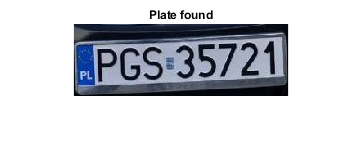


plate = canAreas(FinalCandidate).BoundingBox;

% Define the sections where to crop the plate image
plateBorderX = plate(1);
plateBorderY = plate(2) - 10;
plateIncrementX = plate(3);
plateIncrementY = plate(4) + 10;

finalPlate = [plateBorderX plateBorderY plateIncrementX plateIncrementY];  % Creating a rectangle with the desired dimensions
cropPlate = imcrop(croped, finalPlate);  % Croping the image

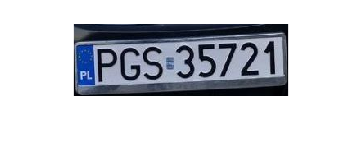


figure(6);
imshow(cropPlate)
title('Found plate')


## Plate cleaning

For the cleaning, a threshold to find dark colors has been defined. This will ensure that the black plate numbers are detected. The reason being the pipeline is defined to work with white and yellow plates but only with black colored plate numbers. Later all small areas and also all elements in contact with the picture borders are set to 0.

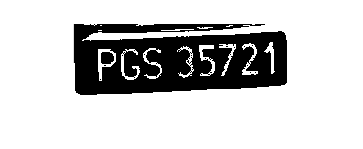

figure;
imshow(cropPlate)
R=cropPlate(:,:,1) < 40;  % values higher than threshold turn to 1 and lower to 0
G=cropPlate(:,:,2) < 40;
B=cropPlate(:,:,3) < 40;

cMask=R.*G.*B;


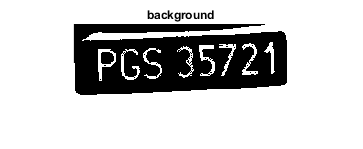

figure;
imshow(cMask)

% Turning all small areas to 0 by creating a zeros matrix the same size of
% the picture and modyfing to 1 the areas bigger to 100. This value has
% been decided by trial and error.
im_label_big = bwlabel(cMask);
background = zeros(size(cropPlate,1),size(cropPlate,2));
for e = 1:max(max(im_label_big )) 
    obj = im_label_big ==e; 
    area = regionprops(obj,'Area').Area; 
    if area > 100
        background = background + obj;
   end
end

imshow(background)
title('background');

### Delete the elements that are stuck around the image:

Clearing all elements in contact with the image borders as explained before.

background = imclearborder(background,8);
disp("Delete the elements that are stuck around the image:");

Delete the elements that are stuck around the image:


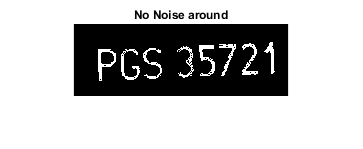

imshow(background)
title('No Noise around');

### Morphological operation on the mask

Dilating the image (plate numbers) to help removing some noise in the numbers and also making the numbers and letters bigger so they are easier to read.

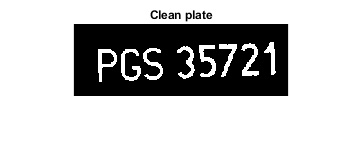

mask3 = strel("square",2);
background =imdilate(background,mask3);
imshow(background)
title("Clean plate")

### Completement the plate

Complementing the plate so the numbers and letter are in black and can be read by the OCR function.

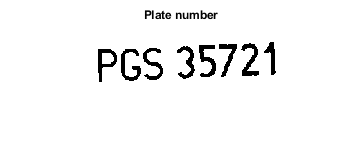

HLeters=1-background;
imshow(HLeters)
title('Plate number');

## Character detection with OCR

Reading the plate number with the OCR function

recognizedText_Nou = [];  % Creating a variable to store the OCR result. This will help to check if the plate was well processed
                          % and could be read.

ocrResults = ocr(HLeters,'TextLayout','Auto'); % Setting the OCR with the automatic Text layout recognition. 
                                               % This will treat the whole image as a block and read it all as a whole.
recognizedText_Nou=ocrResults.Text;               

### Check if no characters are found

In case there is no value inside the defined variable, it can be asumed the initial threshold is not set properly for the current plate. The reason being ilumination. When processing all the training images it could be noticed that ilumination has a huge impact when tresholding the plate. Shades make all pixels darker and light lighter as can be easily understand. The problem with setting a high threshold to read the letters from the better iluminated plates, and therefore having higher intensity blacks, is than some of the low intensity whites from the darker plates can pass throught the filter and then cause interference. The best approach found to deal with this is setting a lower threshold to process poorly iluminated images and later, if the plate number is not well processed due to the blacks having too high of an intensity, checking again with a higher threshold. 

The new threshold has been set to 90 in a trial and error way.

As the code here is a repetition from the code above just to process better iluminated plates, it will not be comented any further until the end of the condition.

if recognizedText_Nou == ""
    disp("No text plate found")
    %Thresholding
    figure;
    imshow(cropPlate)
    % Threshold set due to trial and error.
    R=cropPlate(:,:,1) < 90;  % values higher than threshold turn to 1 and lower to 0
    G=cropPlate(:,:,2) < 90;
    B=cropPlate(:,:,3) < 90;
    
    cMask=R.*G.*B;
    
    figure;
    imshow(cMask)
    
    im_label_big = bwlabel(cMask);
    background = zeros(size(cropPlate,1),size(cropPlate,2));
    for e = 1:max(max(im_label_big )) 
        obj = im_label_big ==e; 
        area = regionprops(obj,'Area').Area;
        if area > 100
            background = background + obj;
       end
    end
    imshow(background)
    title('background');

    %clear background 

    background = imclearborder(background,8);
    disp("Delete the elements that are stuck around the image:");
    imshow(background)
    title('No noise around');

    mask3 = strel("square",2);
    background =imdilate(background,mask3);
    imshow(background)

    HLeters=1-background;
    imshow(HLeters)
    title('Plate number');

    ocrResults = ocr(HLeters,'TextLayout','Auto');
    recognizedText_Nou=ocrResults.Text;
end


## Display the plate number

If yet the plate number could not be read, then raise and error.

if recognizedText_Nou == ""

PLATE NUMBER:


    display('Error reading the plate number. The plate number could not be identified.')

PGS 35721




end

If the plate number could be read, display it.

%---------------------------------------------------------------------------------------------------------------------------------------------------------------
disp("PLATE NUMBER:");                   
disp(recognizedText_Nou);